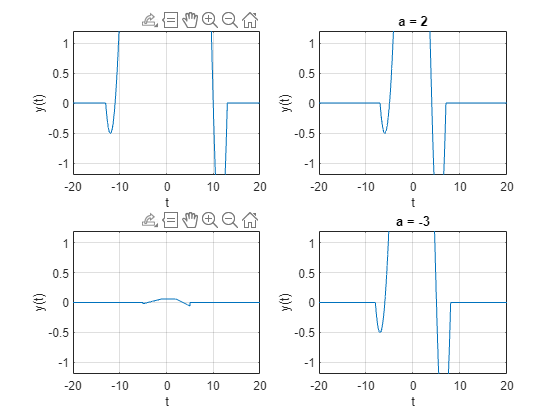

% time range and step size
t = -20:0.01:20;
delta_tau = 0.01;

% x(t) as in Problem 1
x = @(t) ((t >= -5) .* (t <= -1)) .* (t + 4) + ((t > -1) .* (t < 2)) .* 3 + ((t >= 2) .* (t <= 5)) .* (7 - 2*t);

% ha(t) for a = 8, a = 2, a = 0, and a = -3
ha_8 = @(t) ((t >= 0) .* (t <= 8) + (t >= -8) .* (t <= 0));
ha_2 = @(t) ((t >= 0) .* (t <= 2) + (t >= -2) .* (t <= 0));
ha_0 = @(t) ((t >= 0) .* (t <= 0) + (t >= 0) .* (t <= 0));
ha_n3 = @(t) ((t >= 0) .* (t <= 3) + (t >= -3) .* (t <= 0));

% y(t) for each value of a
y_8 = zeros(size(t));
y_2 = zeros(size(t));
y_0 = zeros(size(t));
y_n3 = zeros(size(t));

for i = 1:length(t)
    tau = -20:delta_tau:20;
    y_8(i) = trapz(tau, x(tau).*ha_8(t(i)-tau));
    y_2(i) = trapz(tau, x(tau).*ha_2(t(i)-tau));
    y_0(i) = trapz(tau, x(tau).*ha_0(t(i)-tau));
    y_n3(i) = trapz(tau, x(tau).*ha_n3(t(i)-tau));
end

% plot y(t) for each value of a
subplot(2,2,1)
plot(t, y_8)
title('a = 8')
xlabel('t')
ylabel('y(t)')
ylim([-1.2 1.2])
grid on

subplot(2,2,2)
plot(t, y_2)
title('a = 2')
xlabel('t')
ylabel('y(t)')
ylim([-1.2 1.2])
grid on

subplot(2,2,3)
plot(t, y_0)
title('a = 0')
xlabel('t')
ylabel('y(t)')
ylim([-1.2 1.2])
grid on

subplot(2,2,4)
plot(t, y_n3)
title('a = -3')
xlabel('t')
ylabel('y(t)')
ylim([-1.2 1.2])
grid on